load('QT_Tor_rand.mat')
load('QT_frat.mat')
load('QTnin.mat')
load('QT2.mat')

QT_real=QTn(:,51:100);
RR_real=RRn(:,51:100);

QTm_re=mean(QT_real);
RRm_re=mean(RR_real);

QTv_re=std(QT_real);
RRv_re=std(RR_real);

QTvi_re=QTVin(51:100);

QT_sa=QT2(:,1:43);
QT_sh=QT2(:,44:90);

QTv_sh=std(QT_sh)

QTv_sh =     1.5980    3.2262    3.4329    2.4662    2.3006    3.8075    2.0190    2.2996    3.8005    2.2798    5.0464    1.9650    4.1729    4.1729    3.7182    3.2925    2.9405    3.2259    5.0450    3.9425    3.9861    4.6980    2.9562    4.7572    4.4449    3.7565    2.5474    2.5173    2.5985    6.4870    2.7521    3.5146    4.9767    3.1051    2.2064    7.0090    3.4954    4.7527    2.9198    2.9173    5.9000    3.3423    3.3732   12.5147    3.3160    4.1773    4.0016


QTv_sh(15:48)=QTv_sh(14:47)

QTv_sh =     1.5980    3.2262    3.4329    2.4662    2.3006    3.8075    2.0190    2.2996    3.8005    2.2798    5.0464    1.9650    4.1729    4.1729    4.1729    3.7182    3.2925    2.9405    3.2259    5.0450    3.9425    3.9861    4.6980    2.9562    4.7572    4.4449    3.7565    2.5474    2.5173    2.5985    6.4870    2.7521    3.5146    4.9767    3.1051    2.2064    7.0090    3.4954    4.7527    2.9198    2.9173    5.9000    3.3423    3.3732   12.5147    3.3160    4.1773    4.0016


QTv_sh(14)=std(QTn(:,15))+0.1*rand;
QTv_sh([31,37,45])=[];

QTv_sa=std(QT_sa(:,1:28))

QTv_sa =     1.2767    3.0787    1.7875    2.2198    2.7931    2.7209    2.3055    2.4164    3.1223    1.7671    5.2414    2.1235    4.2610    4.2610    3.5119    2.3994    2.7967    2.8905    3.0814    4.8227    4.1040    3.6782    3.3597    4.7045    3.4701    3.5977    2.9588    2.7754


QTv_sa(15:29)=QTv_sa(14:28);
QTv_sa(14)=QTv_sh(14)+0.1*rand;

QTv_sa(30:45)=QTv_sh(30:45)+0.3*rand(1,16);

QTVi2=log10((var(QT2)./(mean(QT2)).^2)./(var(RR2)./(mean(RR2)).^2));

QTvi_sh=QTVi2(44:90);
QTvi_sh(15:48)=QTvi_sh(14:47)

QTvi_sh =    -2.2753   -1.9722   -2.1054   -2.0963   -1.9967   -2.0756   -2.1142   -2.3633   -2.0580   -1.9930   -2.0654   -2.1852   -1.7369   -1.7369   -1.7369   -2.1599   -1.8907   -1.9514   -2.2079   -1.9004   -1.9002   -2.0410   -2.0632   -2.1299   -2.0783   -1.7524   -1.6239   -2.3673   -1.8259   -2.2670   -1.8696   -1.9409   -2.0696   -1.9065   -2.0217   -1.4422   -2.0597   -1.6087   -1.2844   -1.4324   -1.4303   -1.3247   -1.4406   -1.6906   -1.4241   -1.5936   -1.7924   -1.6821


%QTvi_sh(14)=std(QTn(:,15))+0.1*rand;
QTvi_sh([31,37,45])=[];

ii1=1:1:50;ii1([3,32,35,39,47])=[];
RRm_re=mean(RR_real(:,ii1));
ii2=find(RRm_re>450)

ii2 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    36    42


ii3=find(RRm_re<450)

ii3 =     35    37    38    39    40    41    43    44    45



QTv_ga=std(QTn(:,ii1));
QTv_re=std(QTn(:,ii1+50));
QTv_ga(46:50)=std(QTnin(:,1:5));
QTv_re(46:50)=std(QTnin(:,6:10));
QTv_sh(46:50)=std(QTnin(:,11:15));

QTvi_ga=QTVin(:,ii1);
QTvi_re=QTVin(:,ii1+50);
QTvi_ga(46:50)=QTVinin(:,1:5);
QTvi_re(46:50)=QTVinin(:,6:10);
QTvi_sh(46:50)=QTVinin(:,11:15);

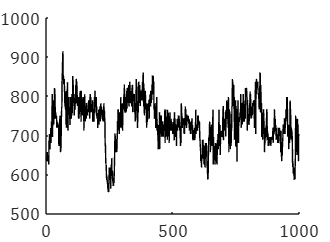

figure
plot(RRn(:,58),'k')
ylim([500 1000])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

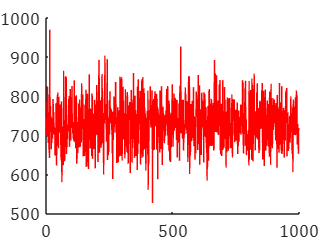

figure
plot(RRn(:,8),'r')
ylim([500 1000])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

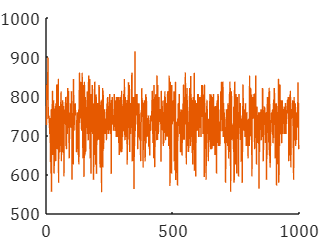

figure
aa=RRn(:,58);ll=length(aa);
rm=randperm(ll);
bb=aa(rm);
plot(bb,'Color',"[0.90 0.35 0]")
ylim([500 1000])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

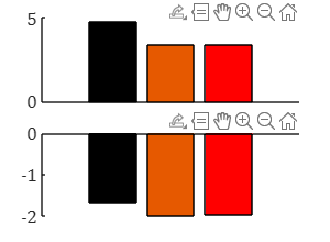

figure
subplot(2,1,1)
xx=[1,2,3];
yy=[mean(QTv_re(ii2)),mean(QTv_sh(ii2)),mean(QTv_ga(ii2))];
ee=[std(QTv_re(ii2)),std(QTv_ga(ii2)),std(QTv_sh(ii2)),std(QTv_sa(ii2))];
bar(xx,yy,'FaceColor','r')
hold on
bar(xx(2),yy(2),'FaceColor','[0.90 0.35 0]')
bar(xx(1),yy(1),'FaceColor','k')
%errorbar(xx,yy,ee,'.b','LineWidth',1)
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
subplot(2,1,2)
xx=[1,2,3];
yy=[mean(QTvi_re(ii2)),mean(QTvi_sh(ii2)),mean(QTvi_ga(ii2))];
ee=[std(QTv_re(ii2)),std(QTv_ga(ii2)),std(QTv_sh(ii2)),std(QTv_sa(ii2))];
bar(xx,yy,'FaceColor','r')
hold on
bar(xx(2),yy(2),'FaceColor','[0.90 0.35 0]')
bar(xx(1),yy(1),'FaceColor','k')
%errorbar(xx,yy,ee,'.b','LineWidth',1)
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';

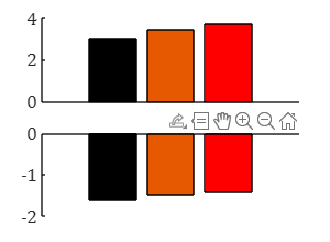

figure
subplot(2,1,1)
ii3(10:14)=[46,47,48,49,50];
xx=[1,2,3];
yy=[mean(QTv_re(ii3)),mean(QTv_sh(ii3)),mean(QTv_ga(ii3))];
ee=[std(QTv_re(ii3)),std(QTv_ga(ii3)),std(QTv_sh(ii3))];
bar(xx,yy,'FaceColor','r')
hold on
bar(xx(1),yy(1),'FaceColor','k')
bar(xx(2),yy(2),'FaceColor','[0.90 0.35 0]')
%errorbar(xx,yy,ee,'.r','LineWidth',1)
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
subplot(2,1,2)
ii3(10:14)=[46,47,48,49,50];
xx=[1,2,3];
yy=[mean(QTvi_re(ii3)),mean(QTvi_sh(ii3)),mean(QTvi_ga(ii3))];
ee=[std(QTv_re(ii3)),std(QTv_ga(ii3)),std(QTv_sh(ii3))];
bar(xx,yy,'FaceColor','r')
hold on
bar(xx(1),yy(1),'FaceColor','k')
bar(xx(2),yy(2),'FaceColor','[0.90 0.35 0]')
%errorbar(xx,yy,ee,'.r','LineWidth',1)
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';

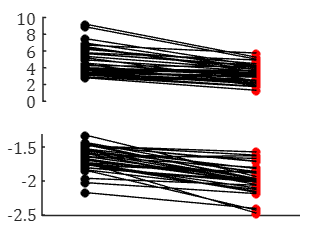

figure
subplot(2,1,1)
QTv_re1=QTv_re(ii2);
QTv_ga1=QTv_ga(ii2);
xx=QTv_re1;xx(:)=1;ii4=1:1:length(xx);ii4(20)=[];
plot(xx(ii4),QTv_re1(ii4),'*k','LineWidth',2)
hold on
xx=QTv_ga1;xx(:)=2;
plot(xx(ii4),QTv_ga1(ii4),'*r','LineWidth',2)
for i1=1:length(ii4)
    plot([1,2],[QTv_re1(ii4(i1)),QTv_ga1(ii4(i1))],'k')
end
xlim([0.75 2.25])
xticks([])
yticks([0 2 4 6 8 10])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
subplot(2,1,2)
QTvi_re1=QTvi_re(ii2);
QTvi_ga1=QTvi_ga(ii2);
xx=QTvi_re1;xx(:)=1;ii4=1:1:length(xx);ii4(20)=[];
plot(xx(ii4),QTvi_re1(ii4),'*k','LineWidth',2)
hold on
xx=QTvi_ga1;xx(:)=2;
plot(xx(ii4),QTvi_ga1(ii4),'*r','LineWidth',2)
for i1=1:length(ii4)
    plot([1,2],[QTvi_re1(ii4(i1)),QTvi_ga1(ii4(i1))],'k')
end
xlim([0.75 2.25])
ylim([-2.52 -1.3])
xticks([])
%yticks([0 2 4 6 8 10])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

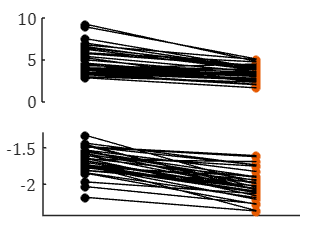

figure
subplot(2,1,1)
QTv_sh1=QTv_sh(ii2);
QTv_ga1=QTv_ga(ii2);
QTv_re1=QTv_re(ii2);
xx=QTv_sh1;xx(:)=2;ii4=1:1:length(xx);ii4(20)=[];
plot(xx(ii4),QTv_sh1(ii4),'*','Color','[0.90 0.35 0]','LineWidth',2)
hold on
xx=QTv_re1;xx(:)=1;
plot(xx(ii4),QTv_re1(ii4),'*k','LineWidth',2)
for i1=1:length(ii4)
    plot([1,2],[QTv_re1(ii4(i1)),QTv_sh1(ii4(i1))],'k')
end
xlim([0.75 2.25])
xticks([])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
subplot(2,1,2)
QTvi_sh1=QTvi_sh(ii2);
QTvi_ga1=QTvi_ga(ii2);
QTvi_re1=QTvi_re(ii2);
xx=QTvi_re1;xx(:)=2;ii4=1:1:length(xx);ii4(20)=[];
plot(xx(ii4),QTvi_sh1(ii4),'*','Color','[0.90 0.35 0]','LineWidth',2)
hold on
xx=QTvi_re1;xx(:)=1;
plot(xx(ii4),QTvi_re1(ii4),'*k','LineWidth',2)
for i1=1:length(ii4)
    plot([1,2],[QTvi_re1(ii4(i1)),QTvi_sh1(ii4(i1))],'k')
end
xlim([0.75 2.25])
xticks([])
ylim([-2.43 -1.3])
yticks([-2 -1.5])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

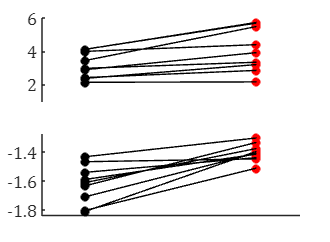

figure
subplot(2,1,1)
QTv_re1=QTv_re(ii3);
QTv_ga1=QTv_ga(ii3);
xx=QTv_re1;xx(:)=1;
plot(xx,QTv_re1,'*k','LineWidth',2)
hold on
xx=QTv_ga1;xx(:)=2;
plot(xx,QTv_ga1,'*r','LineWidth',2)
for i1=1:length(xx)
    plot([1,2],[QTv_re1(i1),QTv_ga1(i1)],'k')
end
xlim([0.75 2.25])
ylim([1 6])
xticks([])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
subplot(2,1,2)
QTvi_re1=QTvi_re(ii3);
QTvi_ga1=QTvi_ga(ii3);
xx=QTvi_re1;xx(:)=1;
plot(xx,QTvi_re1,'*k','LineWidth',2)
hold on
xx=QTvi_ga1;xx(:)=2;
plot(xx,QTvi_ga1,'*r','LineWidth',2)
for i1=1:length(xx)
    plot([1,2],[QTvi_re1(i1),QTvi_ga1(i1)],'k')
end
xlim([0.75 2.25])
ylim([-1.84 -1.27])
xticks([])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)

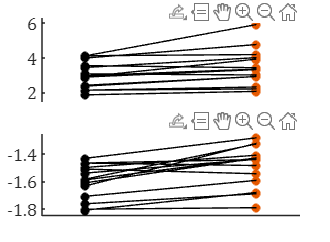

figure
subplot(2,1,1)
QTv_sh1=QTv_sh(ii3);
QTv_ga1=QTv_ga(ii3);
QTv_re1=QTv_re(ii3);
xx=QTv_sh1;xx(:)=2;%ii4=1:1:length(xx);ii4(20)=[];
plot(xx,QTv_sh1,'*','Color','[0.90 0.35 0]','LineWidth',2)
hold on
xx=QTv_ga1;xx(:)=1;
plot(xx,QTv_re1,'*k','LineWidth',2)
for i1=1:length(ii3)
    plot([1,2],[QTv_re1(i1),QTv_sh1(i1)],'k')
end
xlim([0.75 2.25])
ylim([1.5 6.3])
xticks([])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)
h = gca;
h.XTickLabel = {};
h.XAxis.Visible = 'off';
subplot(2,1,2)
QTvi_sh1=QTvi_sh(ii3);
QTvi_ga1=QTvi_ga(ii3);
QTvi_re1=QTvi_re(ii3);
xx=QTvi_sh1;xx(:)=2;%ii4=1:1:length(xx);ii4(20)=[];
plot(xx,QTvi_sh1,'*','Color','[0.90 0.35 0]','LineWidth',2)
hold on
xx=QTvi_ga1;xx(:)=1;
plot(xx,QTvi_re1,'*k','LineWidth',2)
for i1=1:length(ii3)
    plot([1,2],[QTvi_re1(i1),QTvi_sh1(i1)],'k')
end
xlim([0.75 2.25])
%ylim([1.5 6.3])
xticks([])
ylim([-1.85 -1.25])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','off','FontName','Cambria Math','FontSize',12)